% Estimated parameters for MG996R internal DC motor + gearbox
J = 0.01;      % moment of inertia (kg*m^2)
b = 0.001;     % damping coefficient (N*m*s)
K = 0.05;      % motor constant (N*m/A)
R = 2;         % armature resistance (Ohms)
L = 0.005;     % armature inductance (H)

% Define the transfer function 
num = 0.0005;
den = conv([1 0 0], [0.005 2.0005 0.25]);  % Multiply s^2 with the quadratic
G = tf(num, den);

% Display the transfer function
disp('G(s) =');

G(s) =


G


G =
 
               0.0005
  --------------------------------
  0.005 s^4 + 2.001 s^3 + 0.25 s^2
 
Continuous-time transfer function.
Model Properties


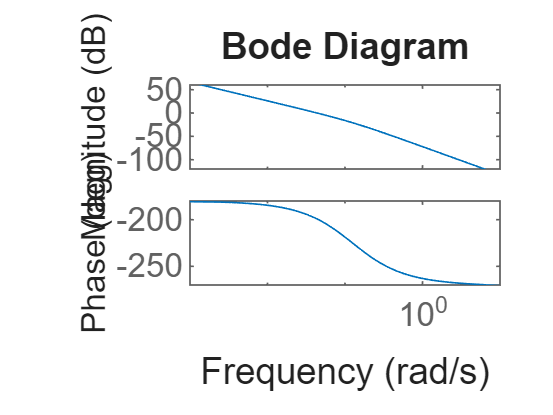


bode(G)

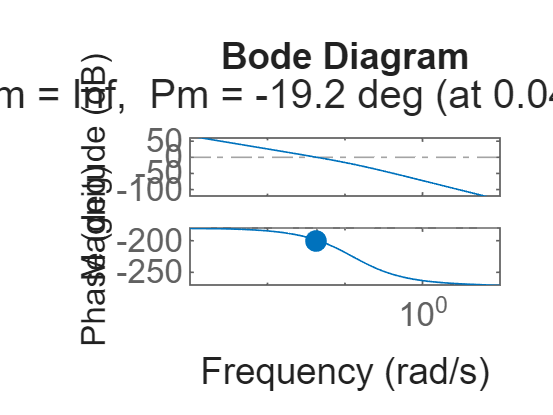

margin(G)

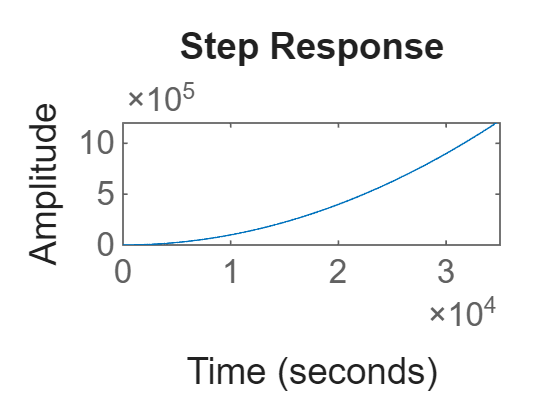

step(G)

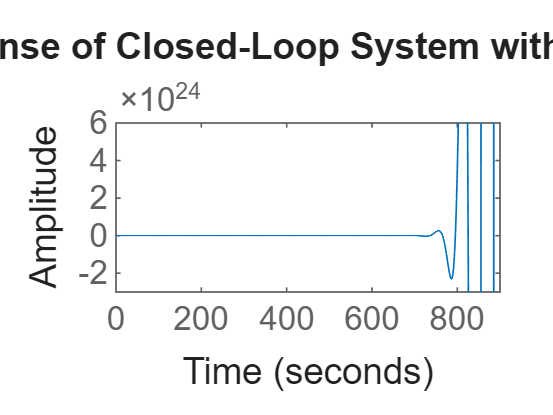


C = pidtune(G, 'PD', 0.05); % Automatically tunes a PID controller
C = pid(4.05, 1.5, 1.69);

T = feedback(G*C, 1);  % Unity feedback

step(T)

title('Step Response of Closed-Loop System with PID Controller')


pole(T)

ans = 1.0e+02 *

  -3.9997 + 0.0000i
  -0.0013 + 0.0007i
  -0.0013 - 0.0007i
   0.0007 + 0.0010i
   0.0007 - 0.0010i



%stepinfo(T)
% sisotool(G)
